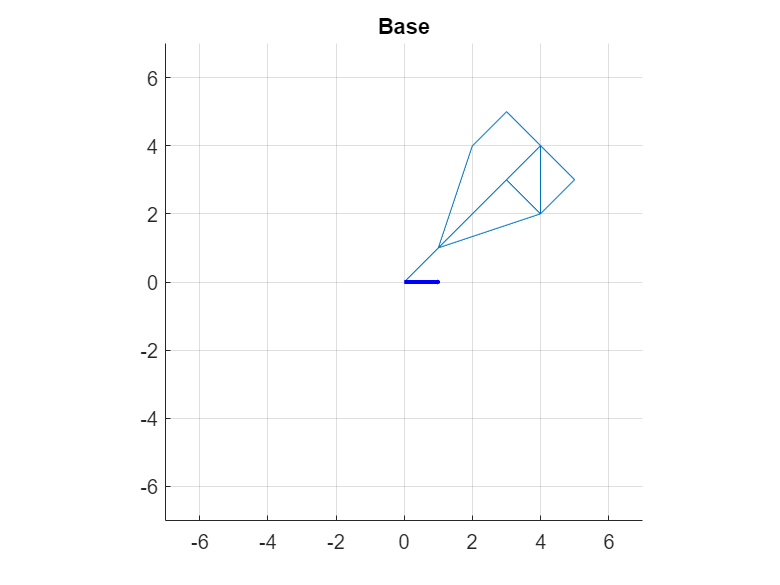

clf
clear
load('MT1A-G9-avbildningar.mat')
origo = [0; 0];

hold on
grid on
axis equal
xlim([-7.0 7.0])
ylim([-7.0 7.0])

X = [0, 1, 2, 3, 4, 5, 4, 3, 4, 4, 1, 3;
     0, 1, 4, 5, 4, 3, 2, 3, 4, 2, 1, 3];
xLine = [1;
         0];


plot(X(1,:), X(2, :))
drawArrow(origo, xLine, 'blue')
title('Base')

% spegel i linjen y = kx
clf
hold on
grid on
axis equal
xlim([-7.0 7.0])
ylim([-7.0 7.0])
disp('-1, ingen förändring i area, rummets orientering ändras')

-1, ingen förändring i area, rummets orientering ändras


dA = det(A)

dA = -1.0000

[V,D] = eig(A)

V =    -0.8660   -0.5000
   -0.5000    0.8660


D =     -1     0
     0     1


mirrorValue = V(2, :)

mirrorValue =    -0.5000    0.8660


k = V(2, 2) / V(2, 1)

k = -1.7321

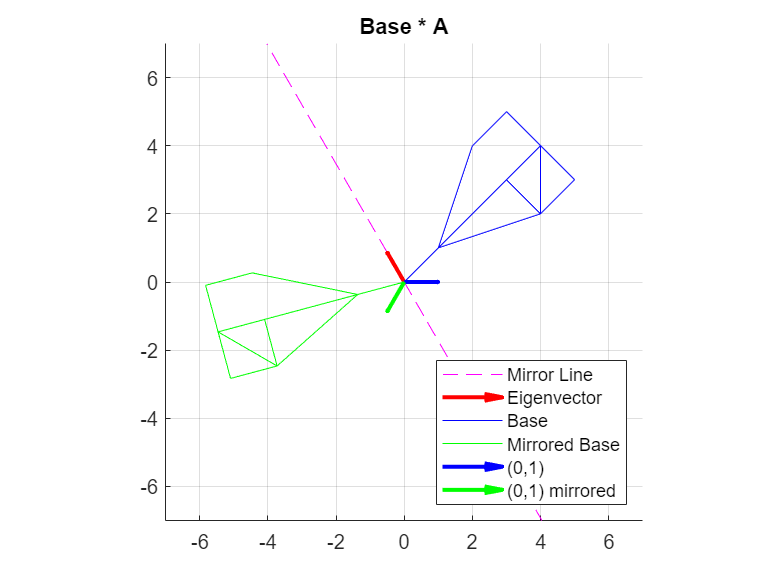

x = linspace(-6, 6);
y = k*x;
Ax = A*X;
AxLine = A*xLine;

plot(x, y, 'magenta--')
drawArrow(origo, V(2, :), 'red')
plot(X(1,:), X(2, :), 'blue')
plot(Ax(1,:), Ax(2, :), 'green')
drawArrow(origo, xLine, 'blue')
drawArrow(origo, AxLine, 'green')

legend('Mirror Line', 'Eigenvector', 'Base', 'Mirrored Base', '(0,1)', '(0,1) mirrored', Location='southeast')
title('Base * A')

% rotationsmatris ca 150 grader
clf
hold on
grid on
axis equal
xlim([-7.0 7.0])
ylim([-7.0 7.0])

Bx = B*X;
BxLine = B*xLine;
plot(X(1,:), X(2, :))
plot(Bx(1,:), Bx(2, :))
drawArrow(origo, xLine, 'blue')
drawArrow(origo, BxLine, 'magenta')

title('Base * B')

sinDelta = norm(BxLine .* xLine)/(norm(BxLine)*norm(xLine))

sinDelta = 0.8660

asind(sinDelta) + 90

ans = 150.0000


cosVradians = dot(BxLine,xLine)/(norm(BxLine)*norm(xLine))

cosVradians = -0.8660

acosd(cosVradians)

ans = 150.0000

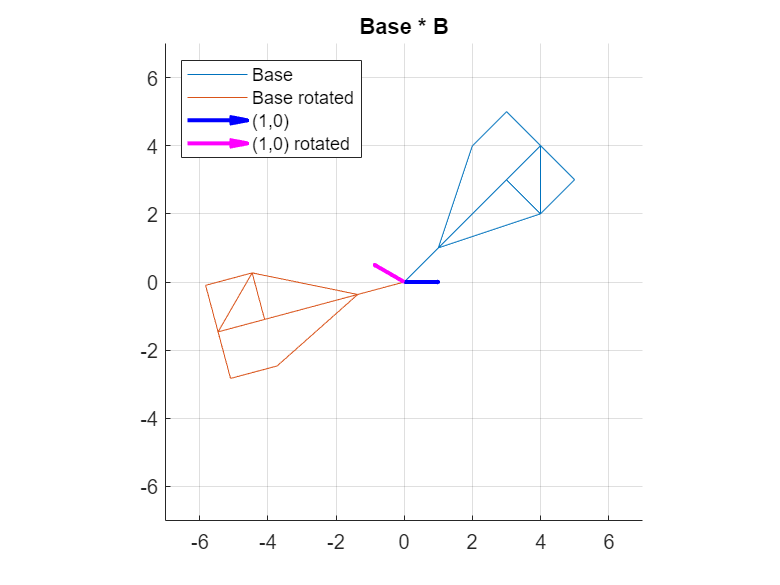

legend('Base', 'Base rotated', '(1,0)', '(1,0) rotated',Location='northwest')

% projektion på värderumet längs V(2,:)
clf
hold on
grid on
axis equal
xlim([-7.0 7.0])
ylim([-7.0 7.0])
[V,D] = eig(C)

V =     0.2588   -0.9659
   -0.9659   -0.2588


D =     0.0000         0
         0    1.0000


drawArrow(origo, V(1,:), 'black')
drawArrow(origo, V(2,:), 'magenta')
Cx = C*X;
CxLine = C*xLine;
plot(X(1,:), X(2, :))
%drawArrow(origo, CxLine)
plot(Cx(1,:), Cx(2, :), 'red')
%drawArrow(C(1,:), C(2,:))


x = linspace(-6, 6);
k = V(2,2)/V(2,1)

k = 0.2679

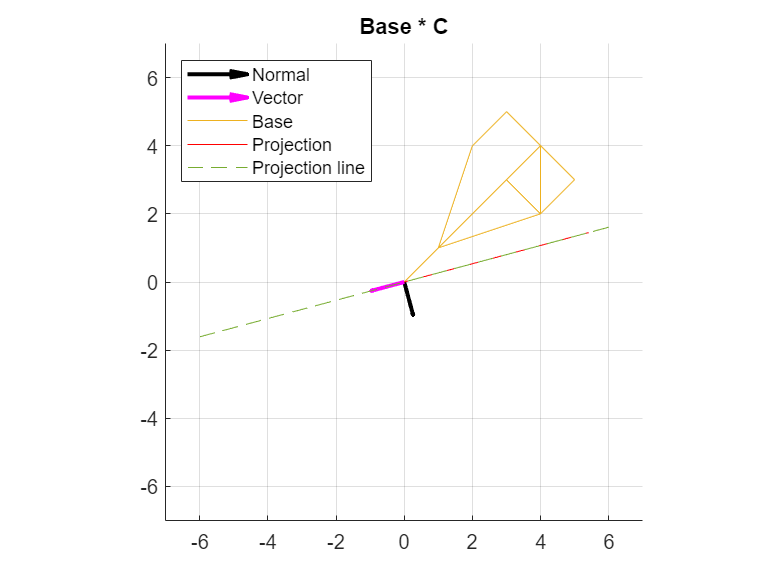

y = k*x;
plot(x, y, '--')

legend('Normal', 'Vector', 'Base', 'Projection', 'Projection line', Location='northwest')
title('Base * C')

% Illustrera begreppet determinant genom avbildning B.
clf
hold on
grid on
axis equal
xlim([-14.0 7.0])
ylim([-14.0 7.0])
b2 = 2*B;
detB2 = det(b2);
detB1 = det(B);
disp('B1 Det:')

B1 Det:


disp('positivt värde ingen förändring i orientering av rummet')

positivt värde ingen förändring i orientering av rummet


sign(detB1)

ans = 1

disp('förändringen i formens area:')

förändringen i formens area:


abs(detB1)

ans = 1

disp('B2 Det:')

B2 Det:


disp('positivt värde ingen förändring i orientering av rummet')

positivt värde ingen förändring i orientering av rummet


sign(detB2)

ans = 1

disp('förändringen i formens area:')

förändringen i formens area:


abs(detB2)

ans = 4

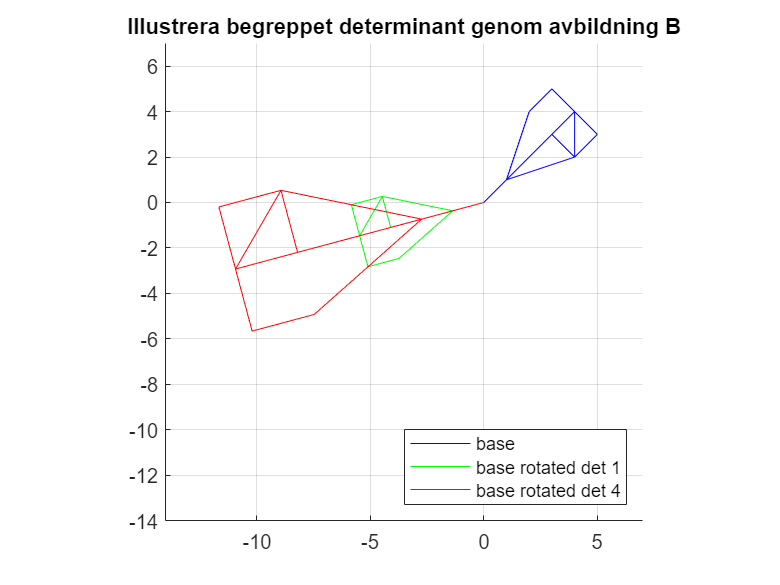

Bx = B*X;
B2x = b2*X;
BxLine = B*xLine;
plot(X(1,:), X(2, :), 'blue')
plot(Bx(1,:), Bx(2, :), 'green')
plot(B2x(1,:), B2x(2, :), 'red')
% drawArrow(origo, xLine, 'blue')
% drawArrow(origo, BxLine, 'magenta')
%drawArrow(origo, B(1, :), 'blue')
%drawArrow(origo, B(2, :), 'magenta')
legend('base', 'base rotated det 1', 'base rotated det 4', Location='southeast')
title('Illustrera begreppet determinant genom avbildning B')

% Illustrera begreppet invers genom avbildning A. Se Not 1.
% Not 1: Det kan inträffa att den aktuella avbildningen saknar invers. 
%        I så fall skall ni illustrera att avbildningen A saknar invers.
% spegel i linjen y = kx
clf
hold on
grid on
axis equal
xlim([-2.0 2.0])
ylim([-2.0 2.0])
detA = det(A)

detA = -1.0000

A

A =    -0.5000   -0.8660
   -0.8660    0.5000


invA = inv(A)

invA =    -0.5000   -0.8660
   -0.8660    0.5000


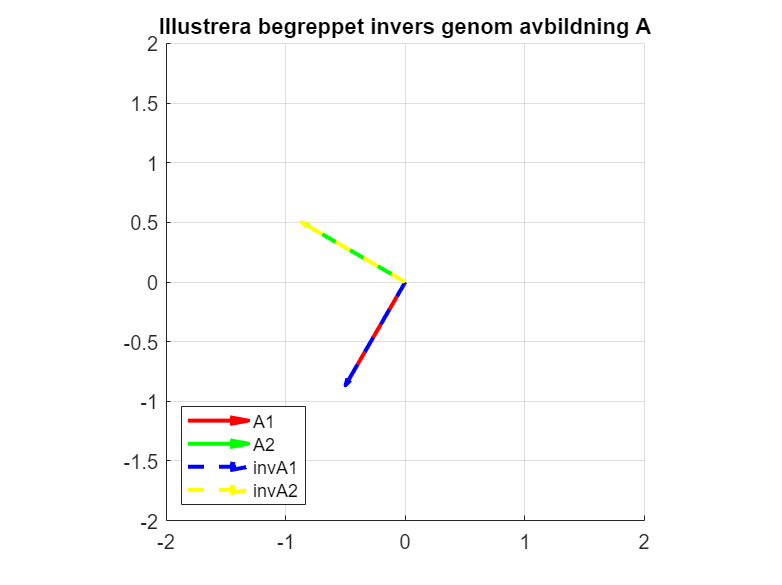


drawArrow(origo, A(1,:), 'red-')
drawArrow(origo, A(2,:), 'green-')

drawArrow(origo, invA(1,:), 'blue--')
drawArrow(origo, invA(2,:), 'yellow--')


legend('A1', 'A2', 'invA1', 'invA2', Location='southwest')
title('Illustrera begreppet invers genom avbildning A')

disp('A is its own inverse')

A is its own inverse


A*A

ans =      1     0
     0     1


% Illustrera begreppen egenvärde och egenvektor genom avbildning A.
clf
hold on
grid on
axis equal
xlim([-7.0 7.0])
ylim([-7.0 7.0])

[V,D] = eig(A);
mirrorValue = V(2, :)

mirrorValue =    -0.5000    0.8660


invCoords = V(1,:)

invCoords =    -0.8660   -0.5000



k = V(2, 2) / V(2, 1)

k = -1.7321

x = linspace(-6, 6);
y = k*x;

coords = V(1,:) * -1

coords =     0.8660    0.5000


mirrorValue * coords'

ans = 0

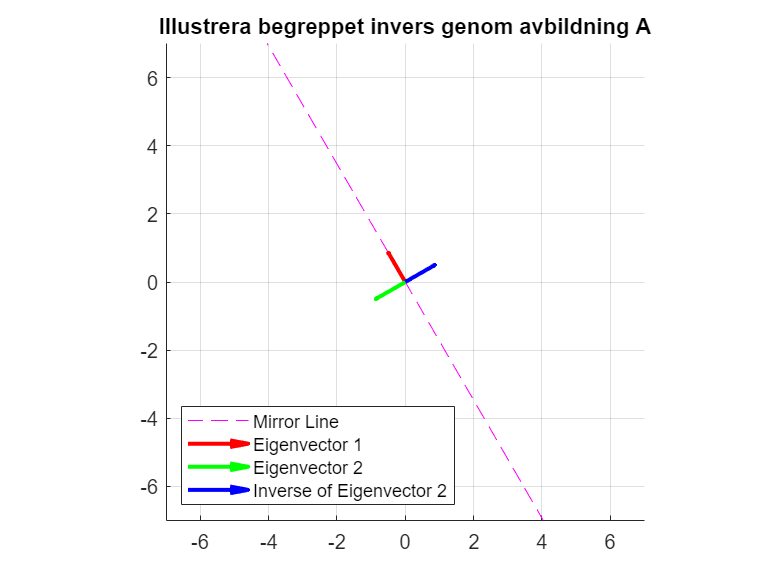



plot(x, y, 'magenta--')
drawArrow(origo, V(2, :), 'red')
drawArrow(origo, V(1,:), 'green')
drawArrow(origo, coords, 'blue')


legend('Mirror Line', 'Eigenvector 1', 'Eigenvector 2', 'Inverse of Eigenvector 2', Location='southwest')
title('Illustrera begreppet invers genom avbildning A')

% Illustrera begreppen nollrum och värderum genom avbildning C.
clf
hold on
grid on
axis equal
xlim([-7.0 7.0])
ylim([-7.0 7.0])

[V,D] = eig(C);
disp('Avrundningsfel, nästan nollrumet')

Avrundningsfel, nästan nollrumet


C * V(1,:)'

ans = 	1.0e+-16 *

         0
   -0.1388


Cx = C*X;
CxLine = C*xLine;

drawArrow(origo, V(1,:), 'black')
drawArrow(origo, V(2,:), 'magenta')
plot(X(1,:), X(2, :))
plot(Cx(1,:), Cx(2, :), 'red')

x = linspace(-6, 6);
k = V(2,2)/V(2,1)

k = 0.2679

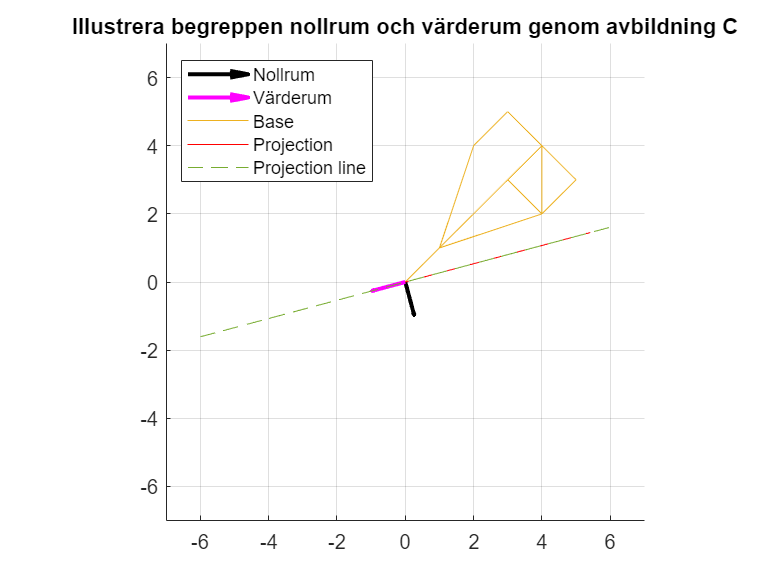

y = k*x;
plot(x, y, '--')

legend('Nollrum', 'Värderum', 'Base', 'Projection', 'Projection line', Location='northwest')
title('Illustrera begreppen nollrum och värderum genom avbildning C')

% Illustrera begreppet sammansatt avbildning genom avbildningarna B och A. Se Not 2.
% Not 2: För den sammansatta avbildningen skall ni klargöra i vilken
%        ordning transformationerna verkar på ert objekt och hur
%        motsvarande matrisprodukt ser ut. Ange vilken avbildningsmatris
%        som skall stå till vänster och vilken avbildningsmatris som
%        skall stå till höger.

clf
hold on
grid on
axis equal
xlim([-7.0 7.0])
ylim([-7.0 7.0])
